load MavLinkStruct;
%load path;

### 1.飞行器的初始条件

%Initial condition
ModelInit_PosE = [0,0,0]; % Vehicle postion xyz in the NED earth frame (m) 位置
ModelInit_VelB = [0,0,0]; % Vehicle speed xyz in the NED earth frame (m/s)  速度
ModelInit_AngEuler = [0,0,0]; % Vehicle Euler angle xyz (roll,pitch,yaw) (rad) 角度
ModelInit_RateB = [0,0,0]; % Vehicle angular speed xyz (roll,pitch,yaw) in the body frame (rad/s) 角速度
ModelInit_RPM = 0; %Initial motor speed (rad/s)   螺旋桨初始转速

### 2.飞行器的模型参数

%UAV model parameter 模型参数
ModelParam_uavMass = 1.4; %Mass of UAV(kg) 质量
ModelParam_uavJxx = 0.0241;  % moment of inertia in body x axis 转动惯量
ModelParam_uavJyy = 0.0239;   % moment of inertia in body y axis
ModelParam_uavJzz = 0.0386;  % moment of inertia in body z axis
ModelParam_uavJ= [ModelParam_uavJxx,0,0;...
    0,ModelParam_uavJyy,0;...
    0,0,ModelParam_uavJzz];   %转动惯量矩阵
ModelParam_uavType = int8(3); % 定义旋翼的布局类型X-type quadrotor refer to "SupportedVehicleTypes.docx" for specific definitions
ModelParam_uavMotNumbs = int8(4);  %Number of motors 电机数量
ModelParam_uavR = 0.225;   %Body radius(m)  飞行器轴距

### 3.飞行器电机相关的参数

该部分内容参考全权的《Introduction to multicopter design and control》的6.3节的内容，如下图所示。

ModelParam_motorCr = 1148; %Motor throttle-speed curve slope(rad/s) 实测拟合得出
ModelParam_motorWb =-141.4;  %Motor speed-throttle curve constant term(rad/s)  实测拟合得出
ModelParam_motorT = 0.02;  %Motor inertia time constant(s) 
ModelParam_motorJm = 0.0001287;    %Moment of inertia of motor rotor + propeller(kg.m^2) 电机转子和螺旋桨的转动惯量
%M=Cm*w^2
ModelParam_rotorCm = 1.779e-07;    %Rotor torque coefficient(kg.m^2)
%T=Ct**w^2
ModelParam_rotorCt = 1.105e-05;    %Rotor thrust coefficient(kg.m^2)
ModelParam_motorMinThr = 0.05;     %Motor throttle dead zone(kg.m^2)

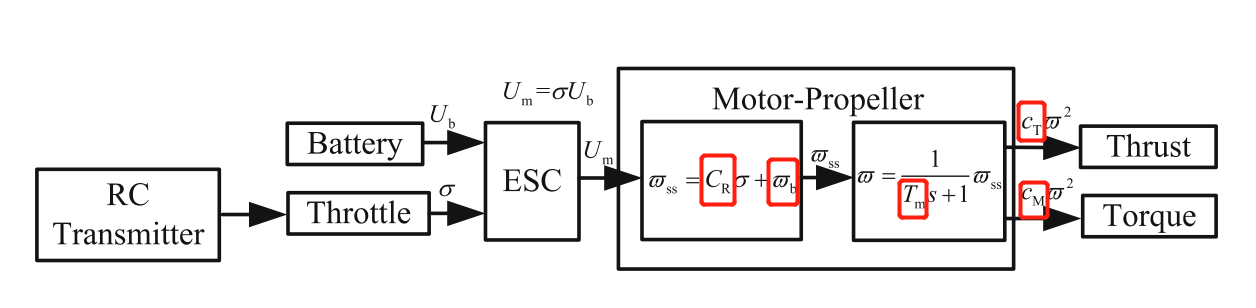

图1 Signal transmission from RC transmitter to thrust and torque

#### 4.飞行器气动相关参数

ModelParam_uavCd = 0.055;   %Damping coefficient(N/(m/s)^2) 阻力系数
ModelParam_uavCCm = [0.0035 0.0039 0.0034]; %Damping moment coefficient vector(N/(m/s)^2)   
ModelParam_uavDearo = 0.12;  %Vertical position difference of Aerodynamic center and gravity center(m)

ModelParam_GlobalNoiseGainSwitch =0;   %Noise level gain

未完待续